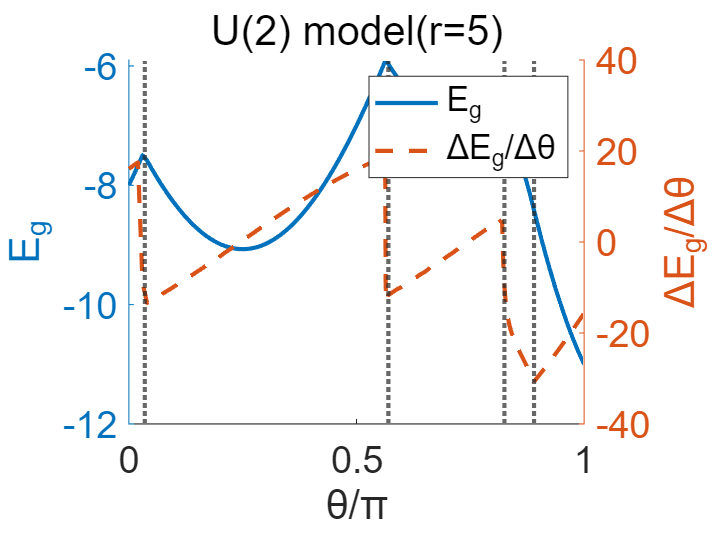

E_g_data=readmatrix('Energy_r5_L32.csv');
theta=E_g_data(1,:);
E_g_matrix=E_g_data(2:3,:);

% 计算 diff(E) 并去掉 theta 的最后一个元素
figure
yyaxis left
%plot(theta,E_g_matrix(2,:),"LineWidth",2,'LineStyle','--')
hold on
plot(theta,E_g_matrix(1,:),"LineWidth",2,'LineStyle','-')
%legend("L=2","L=3")
xlabel('\theta/\pi','FontSize',18)
ylabel('E_g','FontSize',18)


yyaxis right
plot(theta(1:end-1),diff(E_g_matrix(1,:))./(diff(theta)),"LineWidth",2,'LineStyle','--')
% scatter(theta(1:end-1),diff(E_g_matrix(1,:))./diff(theta),'filled','SizeData',30)
xline(0.035,"LineWidth",2,"LineStyle",":")
xline(0.57,"LineWidth",2,"LineStyle",":")
xline(0.825,"LineWidth",2,"LineStyle",":")
xline(0.89,"LineWidth",2,"LineStyle",":")
legend("E_g","\DeltaE_g/\Delta\theta")
ylabel('\DeltaE_g/\Delta\theta','FontSize',18)
grid off
title("U(2) model(r=5)",'FontSize',20)
fig=gcf;
ax=findall(fig,"Type","Axes");
set(ax,"FontSize",18)